In the final step of this exercise, we utilize the spatial information that is uniquely available to us using calcium imaging. Imaging, unlike electrophysiology, allows us to visualize the location of each neuron, and therefore we can make a image that demonstrates the relationship between orientation tuning and location in the brain.

load('PopMap.mat');      

% Variables available:
% AllOSI
% AllPO
% TC
% img, the average projection image you made in Image J
% ROIs, a vector of region of interest data for each cell

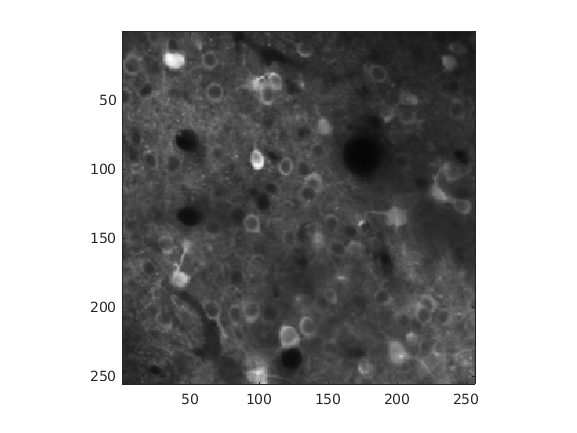

NumCells = size(TC,1); 

% display average projection image
image(img) 
axis square


% setup colors
color = hsv(180); 

Write a for loop across all cells that determines the color based on the neuron's PO. We will plot cells with zero/negative response in black, cells with OSI less than 0.25 in white, and all other cells color-coded to their PO.

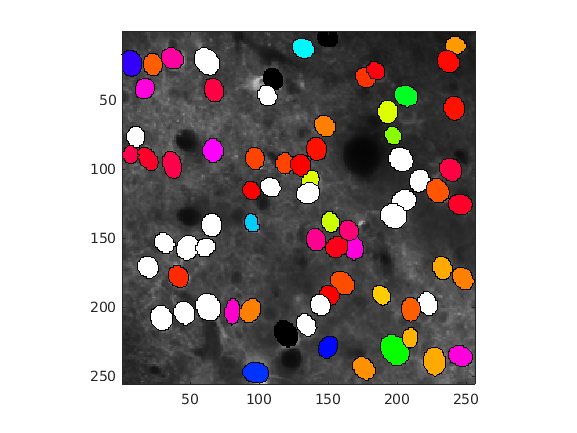

% loop for each cell
for cell = 1:NumCells
    
    % get ROI coordinates
    roi = ROIs{cell}.mnCoordinates;    
    
    % color based on preferred orientation	        
    if max(TC(cell,:)) == 0  % not visually responsive = black
        roicolor = zeros(1,3); 
        
    elseif AllOSI(cell)<0.25 % broadly tuned = white
        roicolor = ones(1,3); 
        
    else % not visually responsive
        roicolor = color(ceil(AllPO(cell)),:);
        
    end    
    
    % draw colored ROI
    patch(roi(:,1),roi(:,2),ones(1,size(roi,1)),'FaceColor',roicolor)    
end     

Plot the final population map.

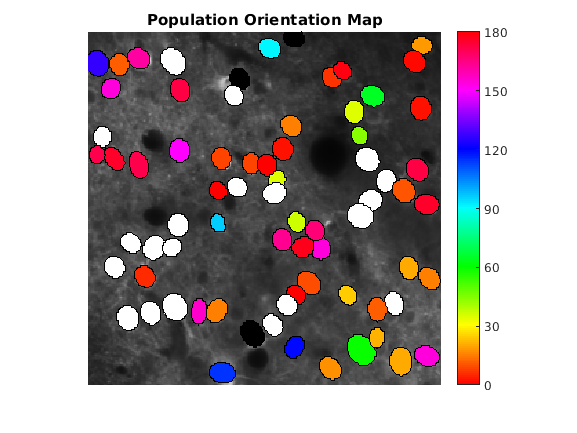

colormap(color)
colorbar('Ticks',[0:60:360]/180, 'TickLAbels',0:30:180)
axis off
title('Population Orientation Map')